## ROBOTICS & CONTROL II PROJECT -  UAVs ON UGV PURSUIT

### Group 11 - Ambrosin Gioele - Andreoli Jacopo - Pastorello Edoardo

clear all
close all

figure_index = 1;

% compute standard trajectories using simulink or load it
traj_sim = false;

Agents initialization with random positions and orientations (ugv always in 0,0,0 wlog).

Extra to be added: network communication - handshaking

% initialize UGV struct
ugv.xw = 0;  ugv.yw = 0; ugv.hw = 0;    % robot position and orientation wrt world frame
ugv.xr = 0;  ugv.yr = 0; ugv.hr = 0;    % robot position and orientation wrt its frame

% define position of visual features of UGV
ugv.P1 = [0.2; 0.15; 0.2];      %[m]
ugv.P2 = [0.2; -0.15; 0.2];     %[m]
ugv.P3 = [-0.2; -0.15; 0.2];    %[m]
ugv.P4 = [-0.2; 0.15; 0.2];     %[m]

% !!! pose wrt its frame is needed only to have the right arrays and matrices dimension

% initialize AUV struct 


formation.alt = 3;                      % formation altitude
formation.r = 3;                        % formation radius
formation.offset = 0.4;                 % altitude and radius offset to perform large movement 
formation.search_alt = 2.5;             % altitude for ugv search operation
formation.search_turn = 0.2;            % turn rate while searching the ugv
formation.search_move = 0.1;            % speed rate while searching ugv


auv.n  = 7;                             % number of auvs
    
auv.id =    zeros(auv.n,1);             % auv id 
auv.xw =    rand(auv.n,1)*6-3 ;         % coords in world frame
auv.yw =    rand(auv.n,1)*6-3 ;
auv.zw =    0.1*ones(auv.n,1);

auv.rollw  =  zeros(auv.n,1);           % roll angle in world frame
auv.pitchw =  zeros(auv.n,1);           % pitch angle in world frame
auv.yaww   =  rand(auv.n,1)*2*pi;       % yaw angle in world frame

auv.xr = zeros(auv.n,1);                % coords in robot frame (UGV)
auv.yr = zeros(auv.n,1);  
auv.zr = zeros(auv.n,1); 
auv = glob2rel(auv,ugv);

auv.rollr = auv.rollw ;                 % we suppose initial roll and pitch
auv.pitchr = auv.pitchw;                % angles will always be zero, only
auv.yawr = auv.yaww - ugv.hw;           % yaw angle may be different

auv.search_inc = zeros(auv.n,1);        % search iterations increments      


% camera parameters:

cam.fov.x = 1.2572;                                 % vertical  fov [rad]
cam.fov.y = 1.4408;                                 % orizontal fov [rad]
cam.f = 3.6*10^-3;                                  % focal length  [m]
cam.ImagePlaneSize = [6.32*10^-3  4.74*10^-3];      % Y x X         [m  m]
cam.PixelDensity = [4000  3000];                    % Y x X - adimensional


Visualize the initial situation with AUVs spawn in random position and UGV located in the center of the scene

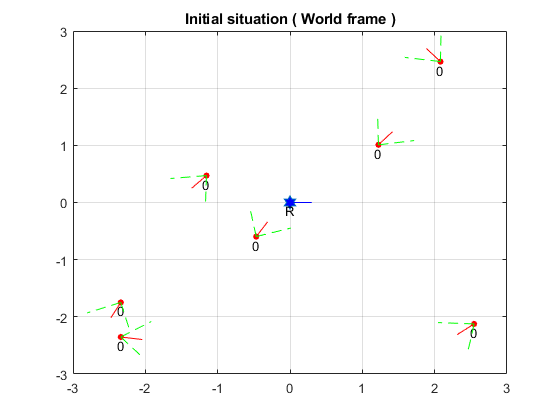

% Check if they are too close to UGV
proximity = 1.5;
for i = 1 : auv.n
    if abs(auv.xw) < proximity
        auv.xw = sign(auv.xw) * proximity;
    end
    if abs(auv.yw) < proximity
        auv.yw = sign(auv.yw) * proximity;
    end
end

% generate labels for plot
labels.auv = generateLabels(auv);

% plot the situation
figure(figure_index);
figure_index = figure_index+1;
plotFlock(auv,ugv,cam,labels.auv);
axis([-3 3 -3 3]);
grid on;

title('Initial situation ( World frame )');

Generate the UGV trajectory and simulate it with the UGV Simulink model

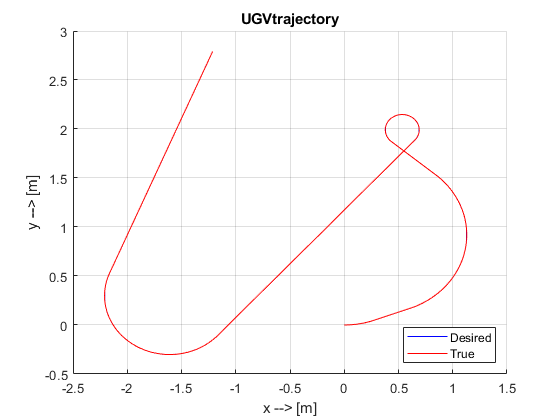

% Run UGV_init (./trajectories_and_controllers) for more details!

% Initialize the Unicycle model
run initializeUnicycleModel.m

% Generate the trajectory
run UGV_trajectory_generation.m

% Set the controller parameters
run UGV_ctrl_params.m

%% simulate
if traj_sim
    open_system('UGV_21a.slx');
    UGVRealPose = sim('UGV_21a.slx', 'ReturnWorkspaceOutputs', 'on');
else
    load("data\UGVRealPose.mat");
end

figure(figure_index);
figure_index = figure_index+1;
hold on
plot(ugv.trajectory.signals.values(:,1), ugv.trajectory.signals.values(:,2), 'b');
%axis([-3 2 -0.5 3]);
grid on;
title('UGVtrajectory');
legendInfo=string(zeros(2,1));
legendInfo(1, 1) = sprintf('Desired');

% plot real trajectory of the ugv
plot(UGVRealPose.Pose.signals.values(:,1), UGVRealPose.Pose.signals.values(:,2), 'r');
legendInfo(2, 1) = sprintf('True');

legend(legendInfo(:,:),'Location','SouthEast');
xlabel('x --> [m]')
ylabel('y --> [m]')

Generate the UAV trajectory and simulate it with the AUV Simulink model. The trajectory is composed by the take-off and the visual search maneuvers that aim to find the UGV.

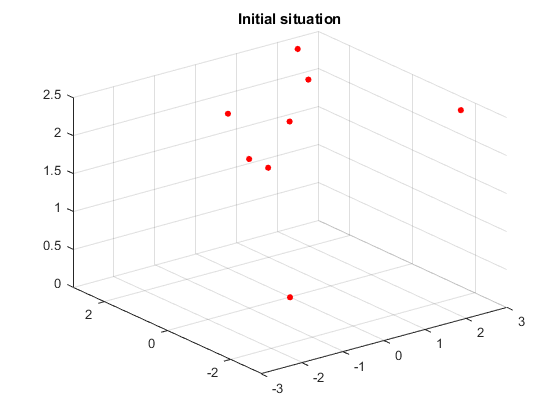

% take off
auv.zr = formation.search_alt * ones(auv.n,1);
auv.zw = auv.zr;

%% we create a UAVSimulationVECTOR as a vector of signals that holds the
% wanted trajectory that each uav must follow. This trajectory is defined
% wrt the initial frame of each UAV
T=55;
UAVSimulation.signals.values = zeros((T-30)/Ts, 4);  % [x, y, z, yaw]
UAVSimulation.time = zeros((T-30)/Ts,1);
%for i=1:1:size(UAVSimulation.time,1)
%    UAVSimulation.time(i)= Ts*i;
%end

UAVSimulationVECTOR = [UAVSimulation UAVSimulation];

for auv_idx=3:auv.n
    UAVSimulationVECTOR = [UAVSimulationVECTOR UAVSimulation];
end

index = 0;
% simulate take-off in 1.5 second
Pose=[0 0 0 0];     % [x, y, z, yaw] initial
NextPose=[0 0 auv.zr(1) 0]; % [x, y, z, yaw] after take-off
elapsed_time = 1.5;
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(1:size(Trajectory,1),:) = Trajectory(:,1:4);
    for i=1:1:size(Trajectory,1)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%% visualize the situation after take-off (simulated)
figure(figure_index);
figure_index = figure_index+1;
plot3([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],'or','MarkerSize',4,'MarkerFaceColor','r')
text([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],labels,'VerticalAlignment','top','HorizontalAlignment','center')
axis([-3 3 -3 3])   
title('Initial situation');
grid on;

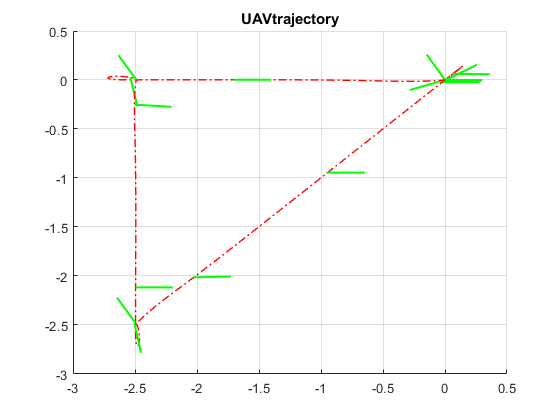


%--------------------------------------------------%

% simulate search in 4.5 second (turn around)
index = elapsed_time / Ts + 1;
Pose=Trajectory(index-1, 1:4);      % [x, y, z, yaw] initial
NextPose=[0 0 auv.zr(1) 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 4.5;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 3 second (go backward)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 0 auv.zr(1) 2*pi];               % [x, y, z, yaw] 
elapsed_time =3;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);
for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 4.5 second (turn around, other direction)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 0 auv.zr(1) 0]; % [x, y, z, yaw] after take-off
elapsed_time = 4.5;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 3 second (go leftwards)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 -2.5 auv.zr(1) 0];               % [x, y, z, yaw] 
elapsed_time =3;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);
for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 4.5 second (turn around)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 -2.5 auv.zr(1) 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 4.5;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% if not found, go back home
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[0 0 0 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 4.9;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[0 0 0 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 0.1;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%---------------------------------------------------%
%---------------------------------------------------%

run initializeQuadrotorModel.m
%run UAV_trajectory_generation.m
% Set the controller parameters
run UAV_ctrl_params.m

clear p_ref;
clear yaw_ref;
 
for j=1:size(UAVSimulationVECTOR(1).signals.values,1)
        p_ref.signals.values(j,1) = UAVSimulationVECTOR(1).signals.values(j,1);
        p_ref.signals.values(j,2) = UAVSimulationVECTOR(1).signals.values(j,2);
        p_ref.signals.values(j,3) = UAVSimulationVECTOR(1).signals.values(j,3);
        yaw_ref.signals.values(j,1) = UAVSimulationVECTOR(1).signals.values(j,4);
end
p_ref.time = UAVSimulationVECTOR(1).time(1:j,:);
yaw_ref.time = UAVSimulationVECTOR(1).time(1:j,:);

if traj_sim
    open_system('UAV_2021_a.slx');
    UAVRealPose = sim('UAV_2021_a.slx', 'ReturnWorkspaceOutputs', 'on');
else
    load("data\UAVRealPose.mat");
end

% plot
figure(figure_index);
figure_index = figure_index+1;
hold on
title('UAVtrajectory');
legendInfo=string(zeros(2,1));
legendInfo(1, 1) = sprintf('Desired');
legendInfo(2, 1) = sprintf('True');

% plot real trajectory
plot3(UAVRealPose.Pose.signals.values(:,1), UAVRealPose.Pose.signals.values(:,2), UAVRealPose.Pose.signals.values(:,3), 'r-.', 'LineWidth', 1);
grid on
% and also yaw angle (occasionally)
for j=1:20:100
    UAV_xd = UAVRealPose.Pose.signals.values(j,1) + 0.3*cos(UAVRealPose.Pose.signals.values(j,6));
    UAV_yd = UAVRealPose.Pose.signals.values(j,2) + 0.3*sin(UAVRealPose.Pose.signals.values(j,6));
    plot3([UAVRealPose.Pose.signals.values(j,1) UAV_xd], [UAVRealPose.Pose.signals.values(j,2) UAV_yd], [UAVRealPose.Pose.signals.values(j,3) UAVRealPose.Pose.signals.values(j,3)], 'g', 'LineWidth', 1.5);
end
for j=101:100:401
    UAV_xd = UAVRealPose.Pose.signals.values(j,1) + 0.3*cos(UAVRealPose.Pose.signals.values(j,6));
    UAV_yd = UAVRealPose.Pose.signals.values(j,2) + 0.3*sin(UAVRealPose.Pose.signals.values(j,6));
    plot3([UAVRealPose.Pose.signals.values(j,1) UAV_xd], [UAVRealPose.Pose.signals.values(j,2) UAV_yd], [UAVRealPose.Pose.signals.values(j,3) UAVRealPose.Pose.signals.values(j,3)], 'g', 'LineWidth', 1.5);
end
for j=401:200:(size(UAVRealPose.Pose.signals.values,1))
    UAV_xd = UAVRealPose.Pose.signals.values(j,1) + 0.3*cos(UAVRealPose.Pose.signals.values(j,6));
    UAV_yd = UAVRealPose.Pose.signals.values(j,2) + 0.3*sin(UAVRealPose.Pose.signals.values(j,6));
    plot3([UAVRealPose.Pose.signals.values(j,1) UAV_xd], [UAVRealPose.Pose.signals.values(j,2) UAV_yd], [UAVRealPose.Pose.signals.values(j,3) UAVRealPose.Pose.signals.values(j,3)], 'g', 'LineWidth', 1.5);
end

hold off


%---------------------------------------------%
%---------------------------------------------%

% create a variable containing the result, like UAVSimulationVECTOR, 1 for
% each drone
% RELATIVE (UAV FRAME)

UAVRealPoseVECTOR=[UAVRealPose UAVRealPose];

for auv_idx=3:auv.n
    UAVRealPoseVECTOR = [UAVRealPoseVECTOR UAVRealPose];
end

% ABSOLUTE (UGV FRAME)

UAVRealPoseVECTOR_abs = UAVRealPoseVECTOR;

% save initial conditions
IC(1,:)=[auv.xr(1) auv.yr(1) auv.zw(1) auv.rollw(1) auv.pitchw(1) auv.yawr(1)];
for auv_idx=1:auv.n
    IC(auv_idx,:) = [auv.xr(auv_idx) auv.yr(auv_idx) 0 0 0 auv.yawr(auv_idx)];
end

for auv_idx=1:auv.n
    % rotation of the trajectory according to auv's heading angle
    traj.x = UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values(:,1);
    traj.y = UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values(:,2);
    traj.x = cos(auv.yawr(auv_idx)) * traj.x - sin(auv.yawr(auv_idx)) * traj.y;
    traj.y = sin(auv.yawr(auv_idx)) * traj.x + cos(auv.yawr(auv_idx)) * traj.y;
    UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values(:,1) = traj.x;
    UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values(:,2) = traj.y;
    UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values = UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values + [auv.xr(auv_idx) auv.yr(auv_idx) 0 0 0 auv.yawr(auv_idx)];
end

As soon as a drone sees the UGV, it enters in the formation. It communicates with other two drones and makes use of pose reconstruction with P4P problem to estimate its the distance wrt the UGV, and at the same time there's consensus among all the drones to establish the disposition of the drones around the UGV.

After formation construction, the UGV (15 s after start) begins to move. The UAVs then perform an iteration of consensus to keep the formation + consensus on measurements (each drone takes two camera images and estimates the motion of the UGV: communicating with the others it can better estimate the true motion of the UGV and move accordingly)

% create two auv structures: out_auv struct for the auvs that don't see the
% ugv yet and form_auv for the auvs that see the ugv and so can go in formation.

out_auv = auv;
form_auv.n = 0;

for i = 1 : out_auv.n
    out_auv.real_traj(i) = UAVRealPoseVECTOR_abs(1,i);
end

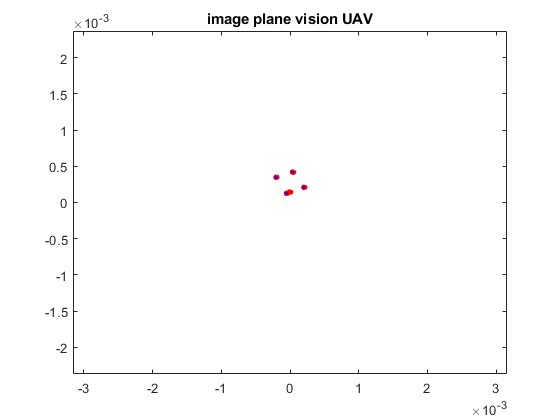

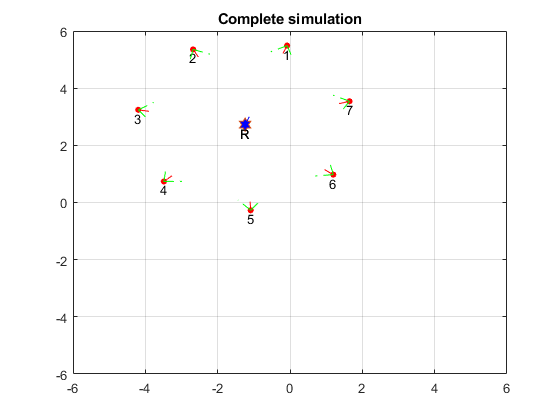

formation.update = false;
formation.complete = false;
formation.number = 0;
n_iteration = 25;
track_idx = 0;
ugv_before = ugv.trajectory.signals.values(1,1);

time = 10;
T1 = 0.01;

% All the simulation: 10 seconds robot is stopped, then it moves
while(time < T*100)
    
    labels.out = generateLabels(out_auv);
    labels.form = generateLabels(form_auv);
    
    out_auv = rel2glob(out_auv,ugv);
    
    figure(figure_index);
    plotFlock(out_auv,ugv,cam,labels.out);
    hold on;
    plotFlock(form_auv,ugv,cam,labels.form);
    hold off;
    lim = formation.r  * 2;
    axis([-lim lim -lim lim ]);
    grid on;
    title("Complete simulation")
%     it=it+1;
 
    pause(.01)
    
    
    
    ugv.xw = ugv.trajectory.signals.values(time*10,1);
    ugv.yw = ugv.trajectory.signals.values(time*10,2);
    ugv.hw = ugv.trajectory.signals.values(time*10,3);
    
    %% --------------- AUVS NOT IN FORMATION
    % check if auvs not in formation see the robot
    rem = [];
    out_auv = glob2rel(out_auv, ugv);
    
    
    for i = 1 : out_auv.n
      
        % use simulation data
        out_auv.xr(i)     = out_auv.real_traj(1,i).Pose.signals.values(time,1);
        out_auv.yr(i)     = out_auv.real_traj(1,i).Pose.signals.values(time,2);
        out_auv.zr(i)     = out_auv.real_traj(1,i).Pose.signals.values(time,3);
        
        out_auv.rollr(i)  = out_auv.real_traj(1,i).Pose.signals.values(time,4);
        out_auv.pitchr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,5);
        out_auv.yawr(i)   = out_auv.real_traj(1,i).Pose.signals.values(time,6);
        
        % Check if the auv see the ugv 
        auv_pos = [out_auv.xr(i)    out_auv.yr(i)     out_auv.zr(i)];
        auv_rpy = [out_auv.rollr(i) out_auv.pitchr(i) out_auv.yawr(i)];
        
        [ip.is_inside1,ip.x1,ip.y1] = computeCameraImage(auv_pos,auv_rpy,ugv.P1.');
        [ip.is_inside2,ip.x2,ip.y2] = computeCameraImage(auv_pos,auv_rpy,ugv.P2.');
        [ip.is_inside3,ip.x3,ip.y3] = computeCameraImage(auv_pos,auv_rpy,ugv.P3.');
        [ip.is_inside4,ip.x4,ip.y4] = computeCameraImage(auv_pos,auv_rpy,ugv.P4.');
    
        if(ip.is_inside1 && ip.is_inside2 && ip.is_inside3 && ip.is_inside4)    
         
        % retrieve its relative position with camera data and add to the formation
            [droneLocation,droneOrientation] = PoseReconstruction([ip.x1 ip.y1; ip.x2 ip.y2; ip.x3 ip.y3; ip.x4 ip.y4]);
            
            out_auv.xr(i)   = droneLocation(1);
            out_auv.yr(i)   = droneLocation(2);
            out_auv.zr(i)   = droneLocation(3);
            out_auv.yawr(i) = atan2(droneOrientation(3,2),droneOrientation(3,3));
            
            out_auv.id(i) = form_auv.n+1;
            form_auv = addToFormation(form_auv,out_auv,i);
            rem(end+1) = i;    
            formation.update = true;
     
        end
    end

    out_auv = removeAuvFrom(out_auv, rem);

        
    %% --------------- AUVS IN FORMATION
    if(form_auv.n > 1) 
        
        form_auv = consensusPolarFormation(form_auv,ugv,formation,0.1,0.2);
        formation.update = false;
        
       if time == 1500
           [estimated.before.x, estimated.before.y, ...
    convex_hull_estimated.before] = pose_estimation(ugv,form_auv,1);
       end
        
       
        if time > 1500
            
%             if time == 2500
%                 form_auv = removeAuvFrom(form_auv, 2);
%             end
%             
%             if time == 3000
%                 form_auv = removeAuvFrom(form_auv, 3);
%                 form_auv = removeAuvFrom(form_auv, 4);
%             end
            % creation of the consensus matrix
            [W, G]= graph_setup(form_auv);
            
            
            
             % Plot the situation
           
        
            form_auv = rel2glob(form_auv,ugv);
            
            j = time*10;
           
  
             % Reconstruct formation if needed
             
             if(form_auv.n ~= formation.number)
                 formation.complete = false;
                 formation.update = true;
                 formation.number = form_auv.n;
             end  
             
             inter_iter = 1;
             MAX_formation_iter = 5;
             if formation.complete == false 
                
                  while(inter_iter <= MAX_formation_iter && formation.complete == false)
                    
                    form_auv = consensusPolarFormation(form_auv,ugv,formation,0.01,5);
            
                    if(max(form_auv.travel_dist) < 0.02 && max(form_auv.th_err) < 0.02)
                        formation.complete = true;    
                    end
                    inter_iter = inter_iter + 1;
                 end
             end
             
             
            
             
            estimated.variation.x = zeros(form_auv.n,1);
            estimated.variation.y = zeros(form_auv.n,1);
        
            
        
            
            ugv_after = ugv.trajectory.signals.values(j,1);
        
            [estimated.after.x, estimated.after.y,... 
                convex_hull_estimated.after, points_image_plane_y] = pose_estimation(ugv,form_auv,j);
          
            yaw_error_vector = -yaw_error(points_image_plane_y, form_auv);
                
            for k= 1:form_auv.n
                estimated.variation.x(k) = estimated.after.x(k) -0; 
                estimated.variation.y(k) = estimated.after.y(k) -0;
                estimated.variation_plot.x(k) = estimated.after.x(k) - estimated.before.x(k);
            end 
        
            [consensus.average.x, average_x, consensus.last.x] = Consensus_iteration(n_iteration, ...
                estimated.variation.x, form_auv, W);
            [consensus.average.y, average_y, consensus.last.y] = Consensus_iteration(n_iteration, ...
                estimated.variation.y, form_auv, W);
            
            if time == 3000
        
                [consensus.average.x_plot, average_x_plot, consensus.last.x_plot] = Consensus_iteration(n_iteration, ...
                estimated.variation_plot.x.', form_auv, W);
                consensus.average.plot = consensus.average.x_plot;
            end
        
        
            track_idx = track_idx + 1;
           % implementation of the motion after the estimation and save the
           % trajectory in a variable
            for k= 1:form_auv.n
                UAV_pursuit_trajectory{track_idx,1} = form_auv.xw;
                UAV_pursuit_trajectory{track_idx,2} = form_auv.yw;
                form_auv.xw(k) = form_auv.xw(k) - consensus.last.x(k);
                form_auv.yw(k) = form_auv.yw(k) - consensus.last.y(k);
                form_auv.yawr(k) = form_auv.yawr(k) + 0.01 * yaw_error_vector(k);
            end 
            
            record_data(i,1) = consensus.last.x(1) ;
            record_data(i,2) = ugv_after-ugv_before;
        
            [temp_x, temp_y] = formation_centre(form_auv);
        
            formation_distance(1,track_idx) = ugv.trajectory.signals.values(j,1) - temp_x;
            formation_distance(2,track_idx) = ugv.trajectory.signals.values(j,2) - temp_y;
            formation_error(track_idx) = sqrt((ugv.trajectory.signals.values(j,1) - temp_x)^2 ...
            +(ugv.trajectory.signals.values(j,2) - temp_y)^2);
        
            % update necessary to make the cycle to continously iterate 
            estimated.before.x = estimated.after.x;
            estimated.before.y = estimated.after.y;
            ugv_before = ugv_after;
            
            form_auv = consensusPolarFormation(form_auv,ugv,formation,0.01,5);
            form_auv = glob2rel(form_auv,ugv);
                    
    
            
        end
        

        % store the desired trajectory
        for i = 1 : form_auv.n
            form_auv.record(i).data(time/10, :) = [ form_auv.xw(i) form_auv.yw(i) form_auv.zw(i) form_auv.yaww(i) T1 time*T1];
        end
        
    end
    
    
  
    time = time + 10;
end


figure_index = figure_index+1;




Now we have 'records', sot the trajectories to be given to Simulink


idx.first_nonempty = 1;
idx.last = T * 10 - 1;

for i = 1 : form_auv.n
    
    form_auv.record(i).traj = form_auv.record(i).data;
    
    while form_auv.record(i).data(idx.first_nonempty,1) == 0
        idx.first_nonempty = idx.first_nonempty + 1;
    end
    
    bias.x   = form_auv.record(i).data(idx.first_nonempty,1);
    bias.y   = form_auv.record(i).data(idx.first_nonempty,2);
    bias.yaw = form_auv.record(i).data(idx.first_nonempty,4);
    
    
    form_auv.record(i).traj(idx.first_nonempty:idx.last,1) = form_auv.record(i).data(idx.first_nonempty:idx.last,1) - bias.x;
    form_auv.record(i).traj(idx.first_nonempty:idx.last,2) = form_auv.record(i).data(idx.first_nonempty:idx.last,2) - bias.y;
    form_auv.record(i).traj(idx.first_nonempty:idx.last,4) = form_auv.record(i).data(idx.first_nonempty:idx.last,4) - bias.yaw;   
end


figure_index = figure_index +1;
save_index = figure_index

save_index = 7

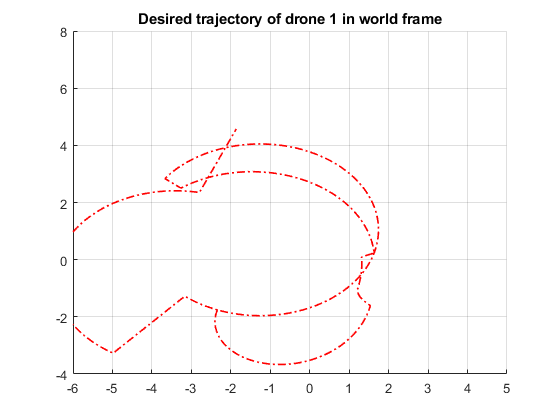

DRONEtoPLOT = 1;
figure(figure_index)
hold on
plot3(form_auv.record(DRONEtoPLOT).traj(:,1)+ IC(DRONEtoPLOT,1), form_auv.record(DRONEtoPLOT).traj(:,2)+ IC(DRONEtoPLOT,2), form_auv.record(DRONEtoPLOT).traj(:,3)+ IC(DRONEtoPLOT,3), 'r-.', 'LineWidth', 1.2);
%plot3(form_auv.record(2).traj(:,1), form_auv.record(2).traj(:,2), form_auv.record(2).traj(:,3), 'g-.', 'LineWidth', 1.2);
%plot3(form_auv.record(3).traj(:,1), form_auv.record(3).traj(:,2), form_auv.record(3).traj(:,3), 'b-.', 'LineWidth', 1.2);
grid on
axis([-6 5 -4 8 0 6])
title("Desired trajectory of drone 1 in world frame")

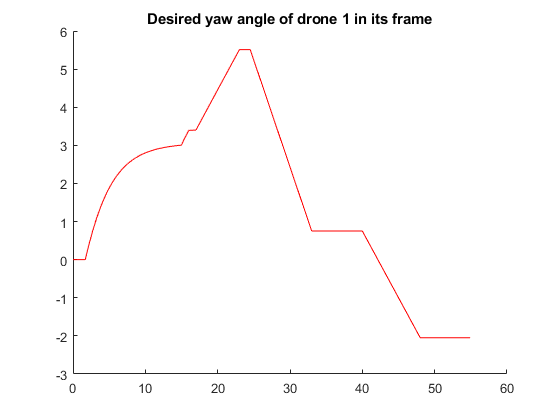

figure_index = figure_index +1;

figure(figure_index)
hold on
title("Desired yaw angle of drone 1 in its frame")
plot(form_auv.record(DRONEtoPLOT).traj(:,6), form_auv.record(DRONEtoPLOT).traj(:,4), 'r');
%plot(form_auv.record(2).traj(:,6), form_auv.record(2).traj(:,4), 'g');
%plot(form_auv.record(3).traj(:,6), form_auv.record(3).traj(:,4), 'b');
hold off

figure_index = figure_index +1;

NEW SIMULATION

run initializeQuadrotorModel.m
%run UAV_trajectory_generation.m
% Set the controller parameters
run UAV_ctrl_params.m

clear UAVRealPoseVECTOR;
UAVRealPoseVECTOR(1,1) = UAVRealPose;
open_system('UAV_2021_a.slx');

for i=1:2
    clear p_ref;
    clear yaw_ref;
     
    for j=1:size(form_auv.record(i).traj(:,1),1)
            p_ref.signals.values(:,1) = form_auv.record(i).traj(:,1);
            p_ref.signals.values(:,2) = form_auv.record(i).traj(:,2);
            p_ref.signals.values(:,3) = form_auv.record(i).traj(:,3);
            yaw_ref.signals.values(:,1) = form_auv.record(i).traj(:,4);
    end
    p_ref.time = form_auv.record(i).traj(:,6);
    yaw_ref.time = form_auv.record(i).traj(:,6);
    
    
    UAVRealPose = sim('UAV_2021_a.slx', 'ReturnWorkspaceOutputs', 'on');
    UAVRealPoseVECTOR(i,1) = UAVRealPose;
end

take to ugv ref frame

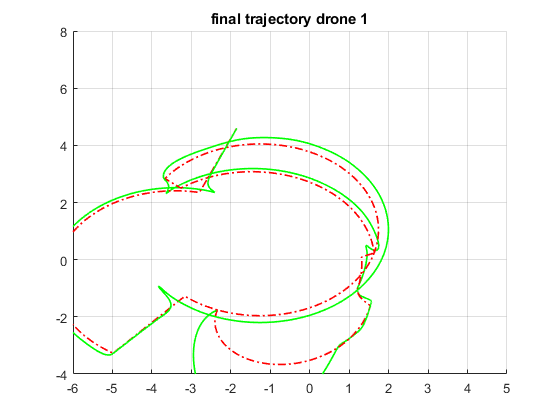

% ABSOLUTE (UGV FRAME)

clear UAVRealPoseVECTOR_abs;
UAVRealPoseVECTOR_abs = UAVRealPoseVECTOR;

for auv_idx=1:2
    UAVRealPoseVECTOR_abs(auv_idx,1).Pose.signals.values = UAVRealPoseVECTOR_abs(auv_idx,1).Pose.signals.values + [IC(auv_idx,1:5) 0];
end

% plot

%figure(figure_index)
figure(save_index)
hold on
title("final trajectory drone 1")
plot3(UAVRealPoseVECTOR_abs(DRONEtoPLOT,1).Pose.signals.values(:,1), UAVRealPoseVECTOR_abs(DRONEtoPLOT,1).Pose.signals.values(:,2), UAVRealPoseVECTOR_abs(DRONEtoPLOT,1).Pose.signals.values(:,3), 'g', 'LineWidth', 1.2);

hold off

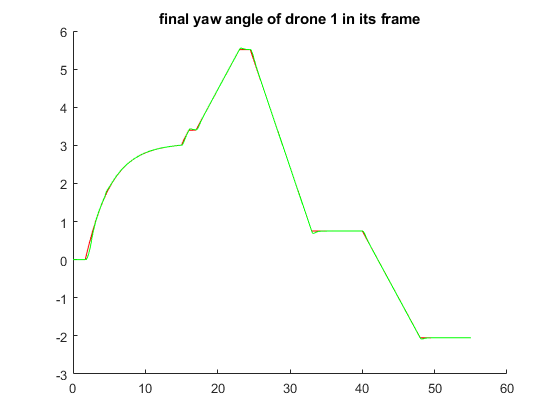

figure_index = figure_index +1;

figure(save_index+1)
hold on
title("final yaw angle of drone 1 in its frame")
plot(UAVRealPoseVECTOR(DRONEtoPLOT).Pose.time(:,1), UAVRealPoseVECTOR(DRONEtoPLOT).Pose.signals.values(:,6), 'g');
hold off

figure_index = figure_index +1;


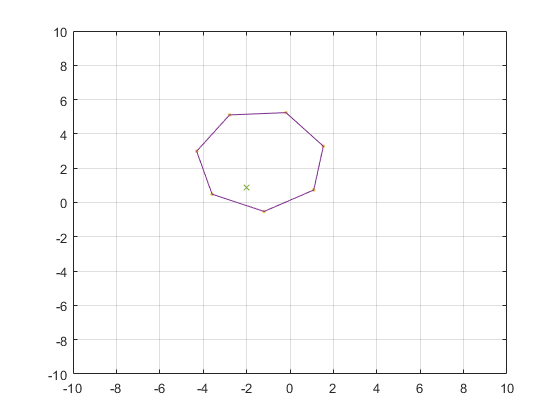

%close all
figure(figure_index)
% plot that consider the final result of formation motion and
% the trajectory followed by the UGV

% UAV_pursuit trajectory save ll the x,y positions of the UAV to store;
vector_of_points = zeros(2, form_auv.n);
for i=1:track_idx
    k = 10000 + i*100;
    if(formation.number == size(UAV_pursuit_trajectory{i,1}))
        
        for j=1:form_auv.n

        point_x = UAV_pursuit_trajectory{i,1}(j);
        point_y = UAV_pursuit_trajectory{i,2}(j);
        vector_of_points(1, j) = point_x;
        vector_of_points(2, j) = point_y;
        active_plot{i,1} = vector_of_points;

        end

    else

        vector_of_points = zeros(2, length(UAV_pursuit_trajectory{i,1}));

        for j=1:size((UAV_pursuit_trajectory{i,1}))
            

            point_x = UAV_pursuit_trajectory{i,1}(j);
            point_y = UAV_pursuit_trajectory{i,2}(j);
            vector_of_points(1, j) = point_x;
            vector_of_points(2, j) = point_y;
            active_plot{i,1} = vector_of_points;

        end
    end
end

% the variable active plot has all the vector of points to plot
close_index = -4;

offset_index = 3;
reduced_index = track_idx/10;
for i=1:(reduced_index+offset_index)

    if(i <= reduced_index)

        iteration_skip = 10*i;
        time = 10000 + i*1000;
        close_index = close_index+1;
    
        vector_of_points = active_plot{iteration_skip,1};
        
        convex_hull_estimated = vector_of_points.';
        [k,av] = convhull(convex_hull_estimated);
        vertix(i) = plot(convex_hull_estimated(:,1),convex_hull_estimated(:,2),'.');
        hold on
        line(i) = plot(convex_hull_estimated(k,1),convex_hull_estimated(k,2));
        axis([-10 10 -10 10])
        grid on;
        hold on
        ugv_plot(i) = plot(ugv.trajectory.signals.values(time,1), ...
            ugv.trajectory.signals.values(time,2), '-x');
        hold on 
        pause(.01);

    else

        close_index = close_index+1;
        delete(vertix(close_index));
        delete(line(close_index));
        delete(ugv_plot(close_index));
        pause(0.75);

    end

    if(close_index > 0 && close_index <= reduced_index+1)

        delete(vertix(close_index));
        delete(line(close_index));
        delete(ugv_plot(close_index));
    
       
    end 



end

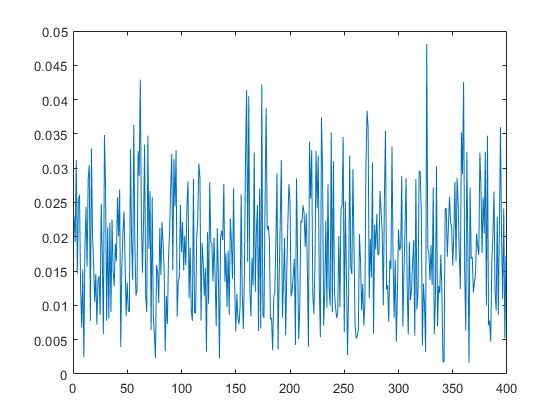

figure_index = figure_index +1;
figure(figure_index)

% variation of the formation error in time (trigger to plot)

plot(formation_error, '-');

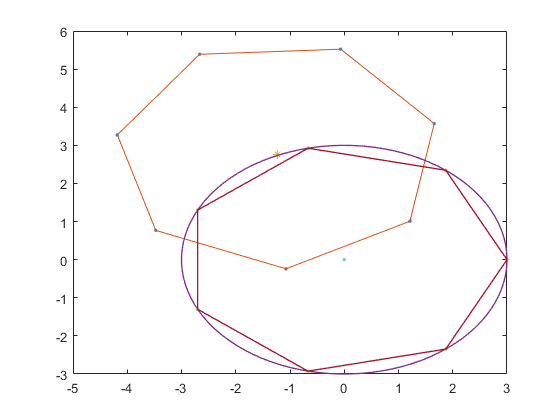


% distance between final formation centre and desired one;
% there also a display of the distance 
figure_index = figure_index +1;
figure(figure_index)

plot_actual_formation(form_auv);
hold on 
[temp_x, temp_y] = formation_centre(form_auv);
plot(temp_x, temp_y,'*');
hold on;
correct_formation(ugv, form_auv,j);

% here j = 40000, namely final sample og the ugv trajectory
string = 'final formation distance: ';   
value = formation_error(1, 25);
X = [string, num2str(value)];

disp(X);

final formation distance: 0.0086118


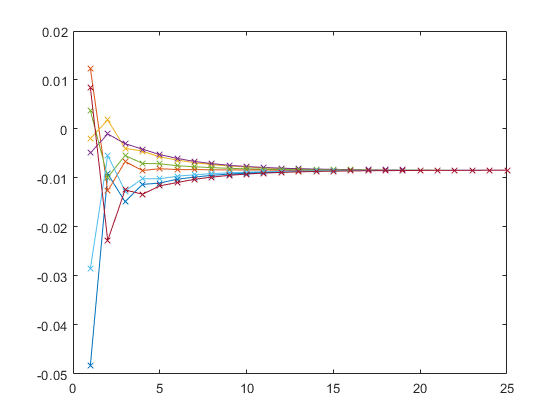

figure_index = figure_index +1;
figure(figure_index)
% plot that show dynamics of the convergence of distributed 
% estimation between the estimation of subsequent iteration
% in the above loop (in particular last one estimation)

convergence_UAV = zeros(n_iteration ,form_auv.n); 
for i = 1 : n_iteration
    for j = 1:form_auv.n
     convergence_UAV(i,j) = consensus.average.plot{i}(j);
    end
end

for k = 1:form_auv.n
     plot(convergence_UAV(:,k), '-x')
     hold on
end